# Train Neural Network with Image Data

If you have a data set of images, then you can train a deep neural network using an image input layer.

Unzip the digit sample data and create an image datastore. The `imageDatastore` function automatically labels the images based on folder names.

unzip("DigitsData.zip")

imds = imageDatastore("DigitsData", ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

Divide the data into training and test data sets, so that each category in the training set contains 750 images, and the test set contains the remaining images from each label. `splitEachLabel` splits the image datastore into two new datastores for training and test.

numTrainFiles = 750;
[imdsTrain,imdsTest] = splitEachLabel(imds,numTrainFiles,"randomized");

Define the convolutional neural network architecture. Specify the size of the images in the input layer of the network and the number of classes in the final fully connected layer. Each image is 28-by-28-by-1 pixels.

inputSize = [28 28 1];
classNames = categories(imds.Labels);
numClasses = numel(classNames);

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];

Specify the training options.

- Train using the SGDM solver.

- Train for four epochs.

- Monitor the training progress in a plot and monitor the accuracy metric.

- Disable the verbose output.

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    Verbose=false, ...
    Plots="training-progress", ...
    Metrics="accuracy");

Train the neural network. For classification, use cross-entropy loss.

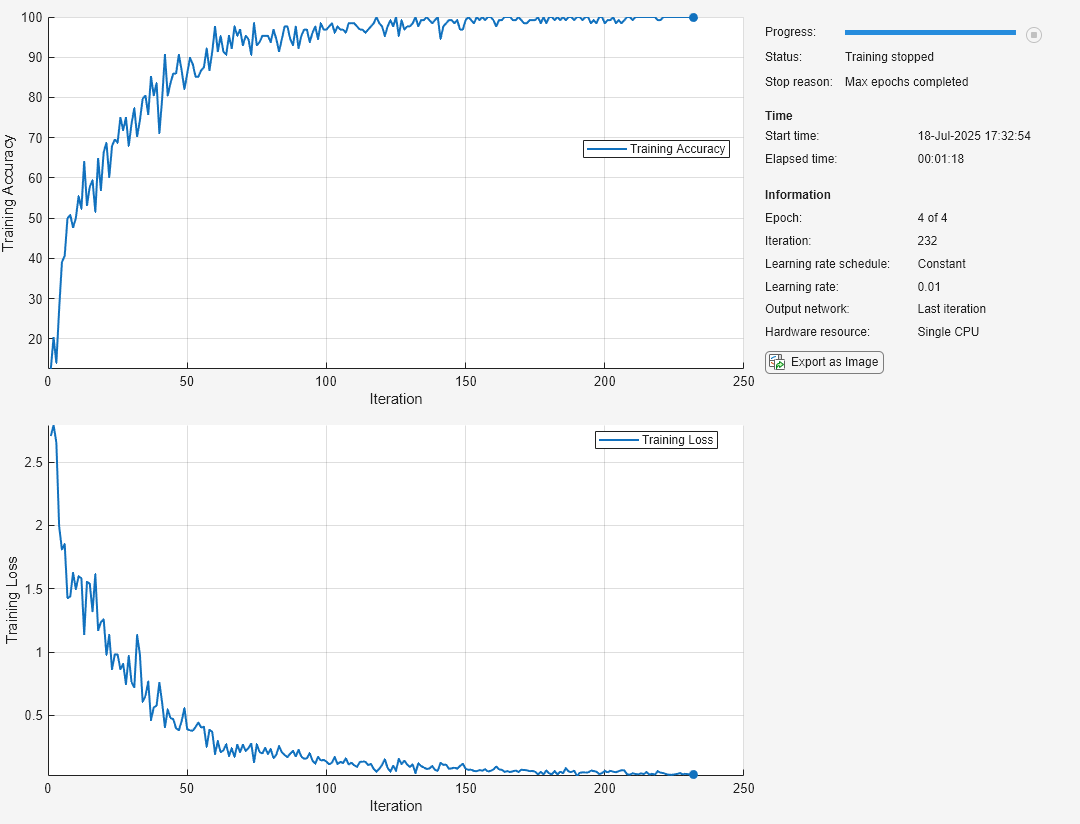

net = trainnet(imdsTrain,layers,"crossentropy",options);

Test the network using the labeled test set. For single-label classification, evaluate the accuracy. The accuracy is the percentage of the labels that the network predicts correctly.

accuracy = testnet(net,imdsTest,"accuracy")

accuracy = 98.2400

Predict the classification scores using the trained network, then convert the labels to predictions using the `scores2label` function.

scoresTest = minibatchpredict(net,imdsTest);
YTest = scores2label(scoresTest,classNames);

Visualize the predictions in a confusion chart.

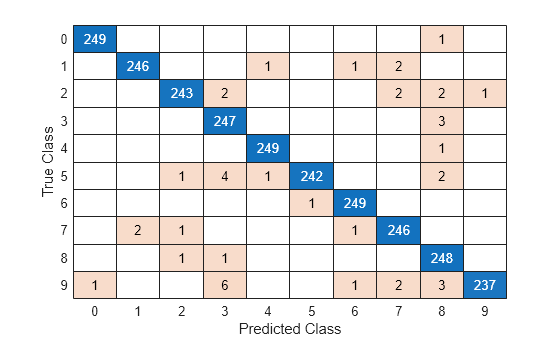

confusionchart(imdsTest.Labels,YTest)

*Copyright 2023-2024 The MathWorks, Inc.*